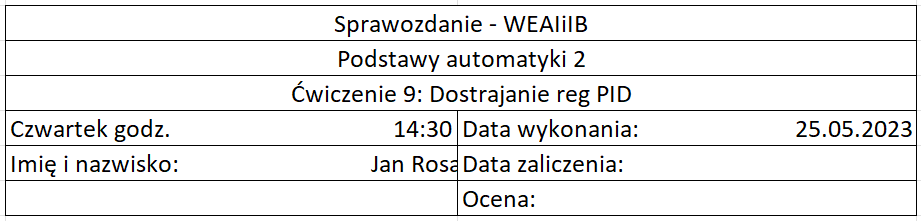

## Wstęp

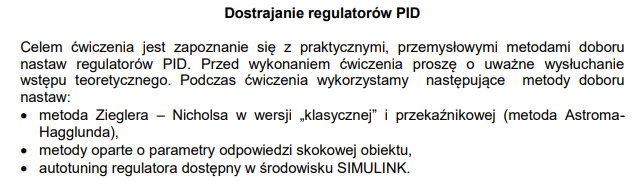

## Przebieg Ćwiczenia

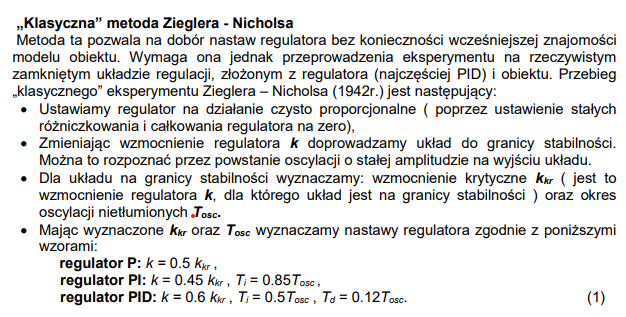

P = 1; I = 0; D = 0;

figure;
hold on;
PIDtest();
P=2;
PIDtest();
P=3.35;
PIDtest();
legend(["kp = 1" "kp = 2" "kp = 3.4"])
hold off;

%[czas, y] = ginput(2)
T = 167.0221 - 90.884

T = 76.1381

kkryt = 3.3

kkryt = 3.3000

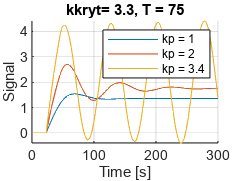

title("kkryt= 3.3, T = 75")


figure;
hold on;
P = 0.5 * kkryt

P = 1.6500

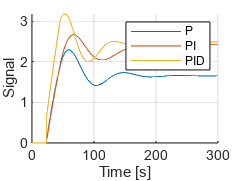

PIDtest();
P= 0.45 * kkryt; I = 1/(0.85*T);
PIDtest();
P= 0.6 * kkryt; I = 1/(0.5*T); D = 0.12*T;
PIDtest();
legend(["P" "PI" "PID"])
hold off;

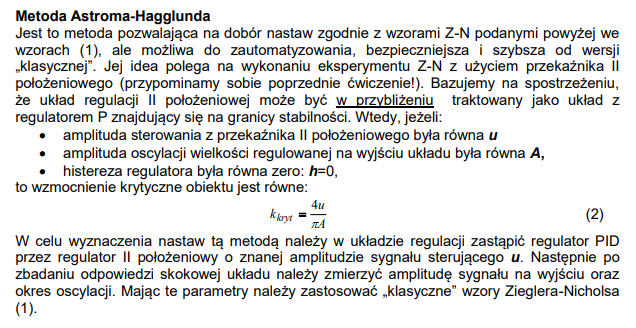

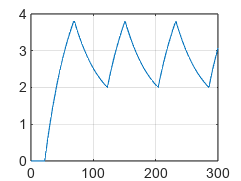

figure;
out = sim("model.slx");
plot(out.RScopeData1.time, out.RScopeData1.signals.values);
grid on;

u = 4;
A = 1.7;
kkryt = 4*u/(pi * A)

kkryt = 2.9959

T = 80;

figure;
hold on;
P = 0.5 * kkryt

P = 1.4979

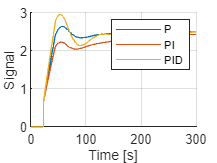

PIDtest();
P= 0.45 * kkryt; I = 1/(0.85*T);
PIDtest();
P= 0.6 * kkryt; I = 1/(0.5*T); D = 0.12*T;
PIDtest();
legend(["P" "PI" "PID"])
hold off;

## Dostrajanie regulatora PID na podstawie parametrów transmitancji zastępczej

k = 1.18; Tob = 45; tau = 22;
kkryt = 0.95/(T/tau)
I = 1/(2.4*tau)
D = 0.5 * tau
figure
PIDtest()



Użycie funkcji „Autotune” dostępnej w środowisku SIMULINK

Dobrze wyglądające sterowanie

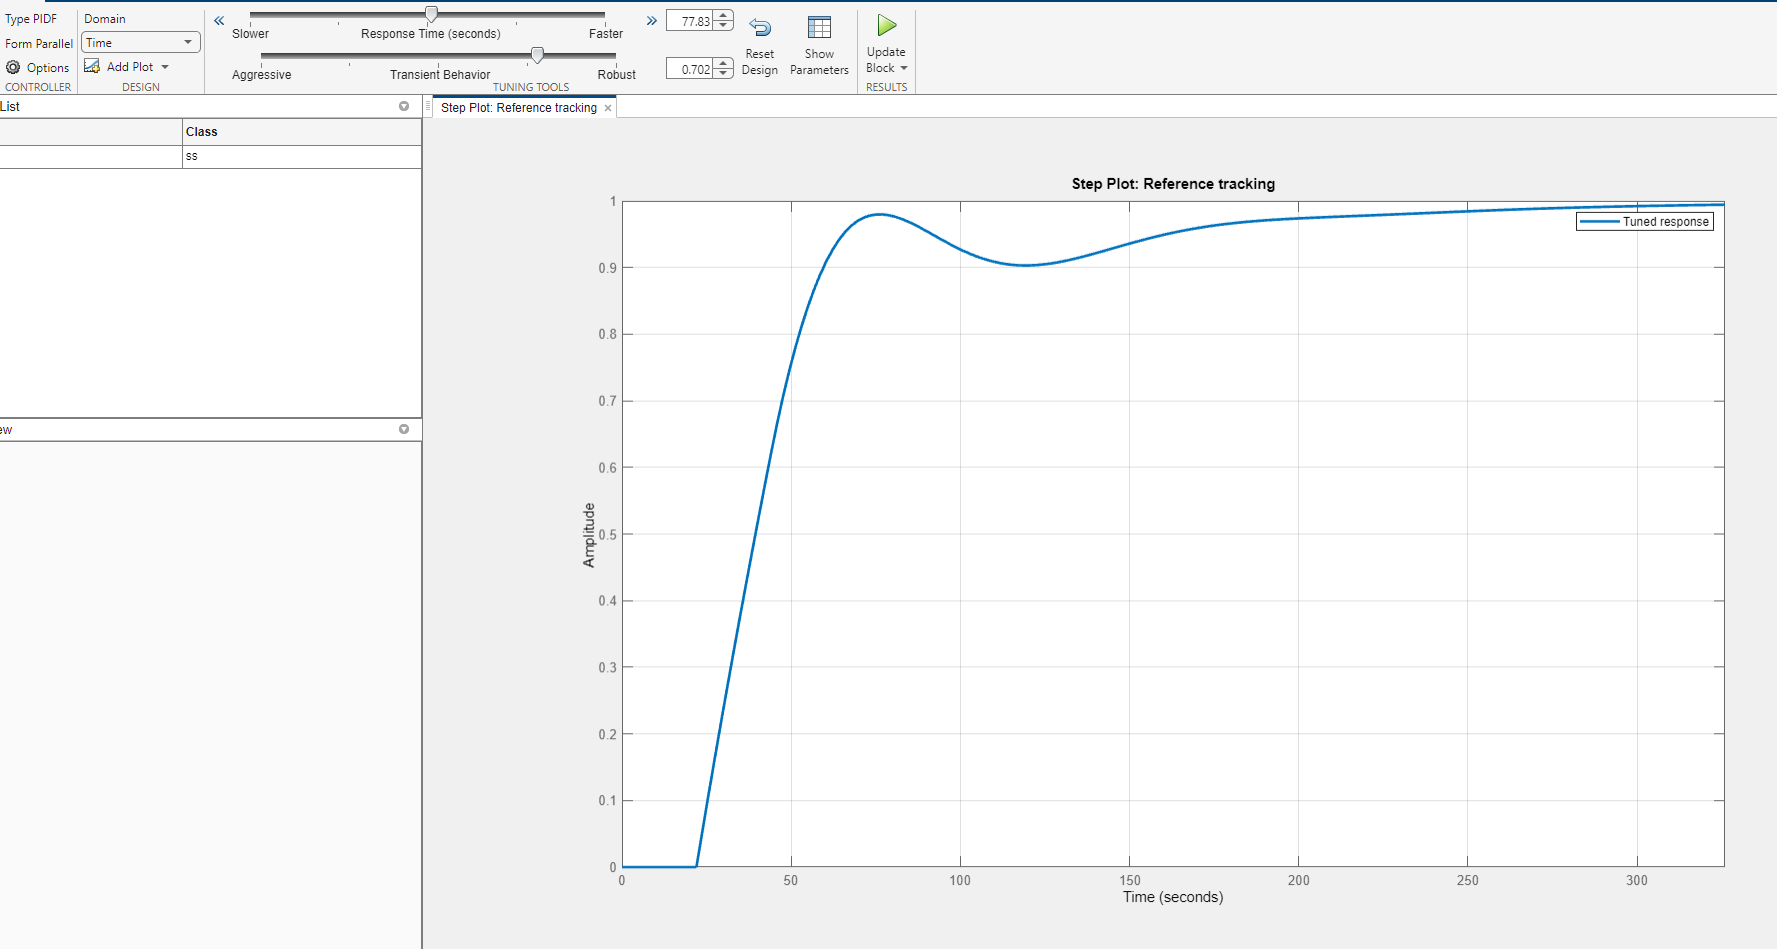

Najprawdopodobniej błędy symulacji

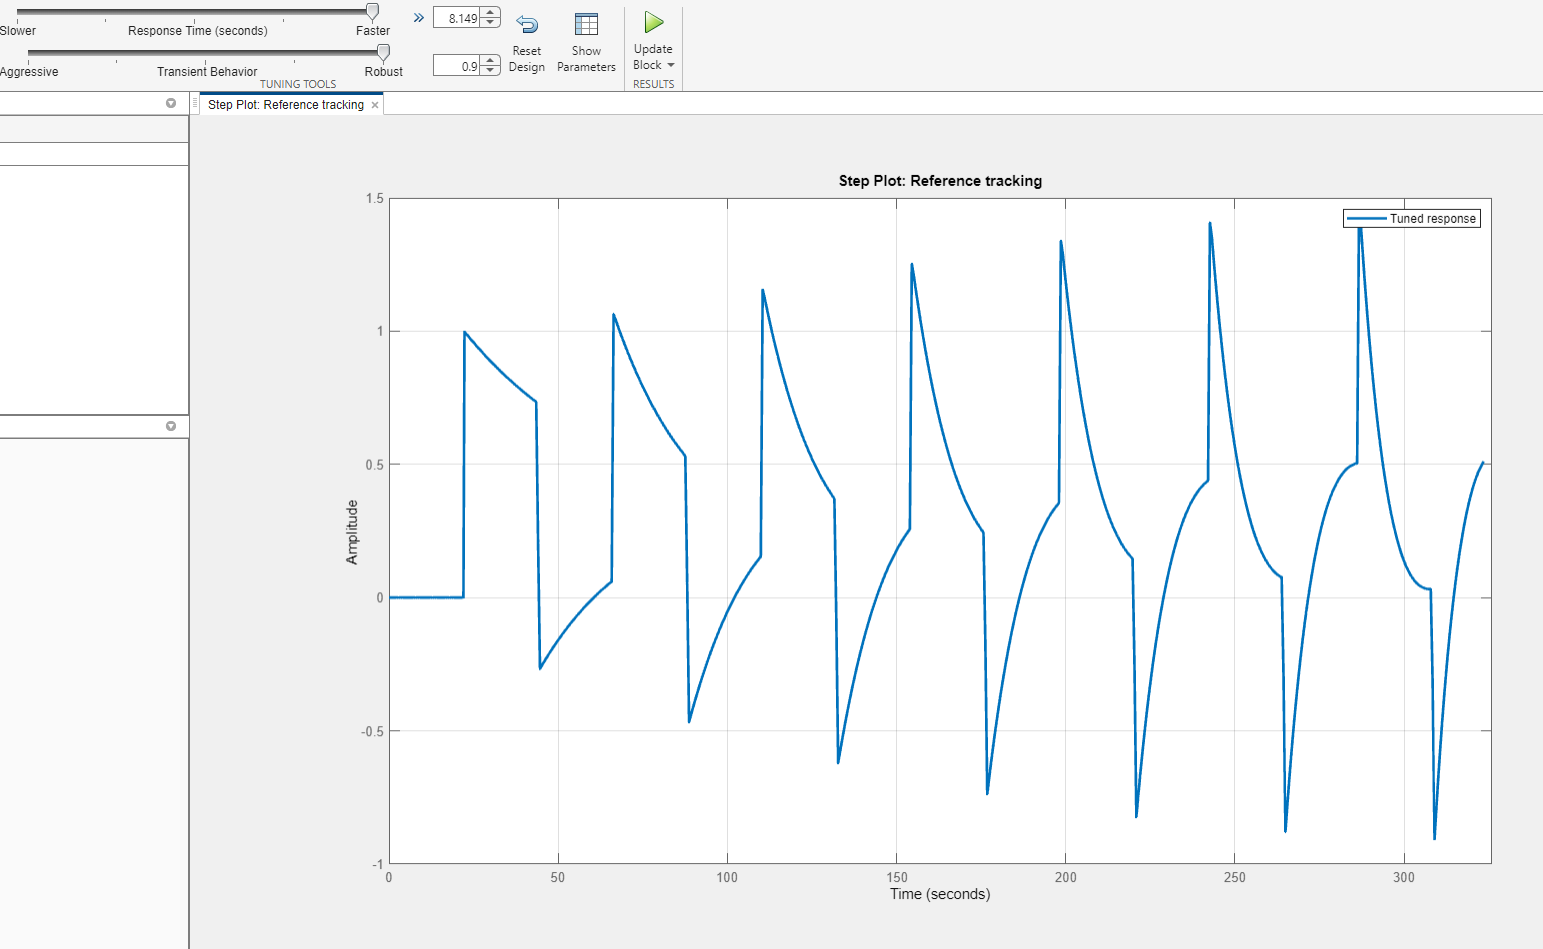

Ogromne przesterowania

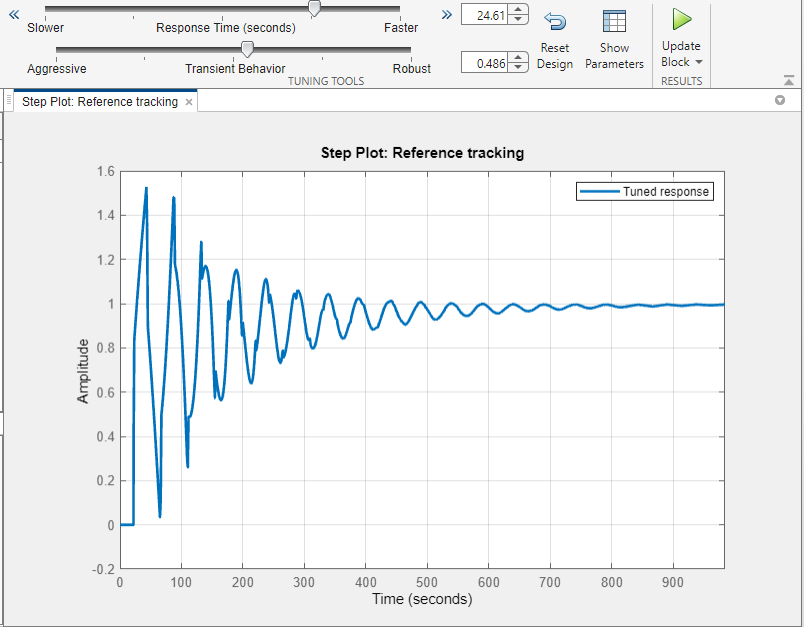

Wolne Sterowanie bez przesterowań i żadnego ślau oscylacji

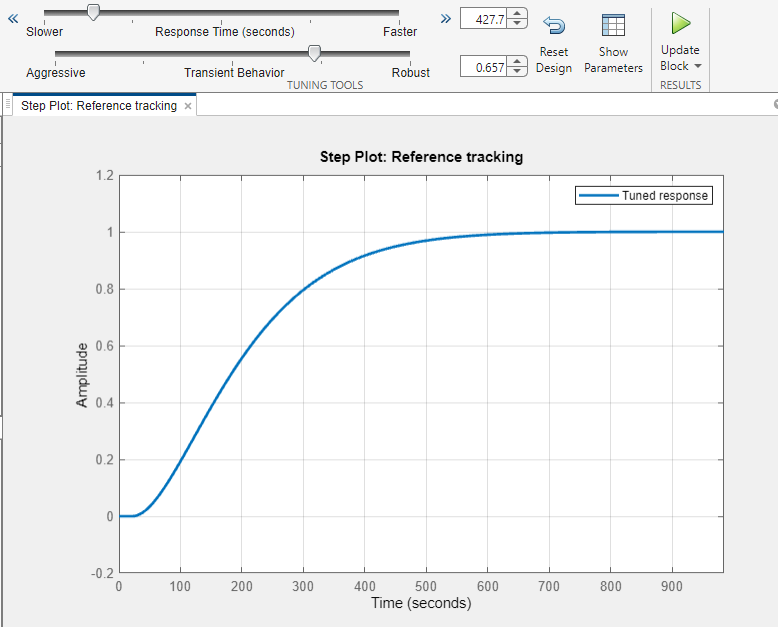

function [] = PIDtest()
    pidsim = sim("model.slx");
    plot(pidsim.PIDScopeData.time, pidsim.PIDScopeData.signals.values)
    xlabel("Time [s]")
    ylabel("Signal")
    grid on;
end

## Wnioski

Wnioski z ćwiczenia dotyczące dostrajania regulatorów PID są następujące:

1. Metoda Zieglera-Nicholsa (klasyczna i metoda Astroma-Hagglunda) oraz metody oparte na parametrach odpowiedzi skokowej obiektu są skutecznymi technikami doboru nastaw regulatorów PID.

2. Metoda Zieglera-Nicholsa "klasyczna" wymaga przeprowadzenia eksperymentu na rzeczywistym zamkniętym układzie regulacji. Identyfikuje się granicę stabilności i wyznacza wzmocnienie krytyczne oraz okres oscylacji. Następnie na podstawie tych parametrów dobiera się nastawy regulatora PID.

3. Metoda Astroma-Hagglunda opiera się na wykorzystaniu przekaźnika II położeniowego do identyfikacji wzmocnienia krytycznego obiektu. Następnie nastawy regulatora PID są wyznaczane zgodnie z wzorami Zieglera-Nicholsa.

4. Metody oparte na parametrach odpowiedzi skokowej obiektu zakładają modelowanie obiektu regulacji jako transmitancję zastępczą z opóźnieniem. Nastawy regulatora PID są wyliczane na podstawie założonych wskaźników jakości, takich jak przeregulowanie czy czas regulacji.

5. Wykorzystanie funkcji "Autotune" dostępnej w środowisku SIMULINK zapewnia automatyczne dostrajanie nastaw regulatora PID na podstawie eksperymentów z różnymi parametrami odpowiedzi skokowej.

6. Porównując wyniki zastosowania różnych metod doboru nastaw regulatora PID, można zauważyć różnice w nakładzie pracy i efektywności dostrajania. Metoda Astroma-Hagglunda jest bardziej zautomatyzowana i szybsza w porównaniu do metody klasycznej Zieglera-Nicholsa, ale wyniki mogą się nieznacznie różnić.

7. Dobór odpowiednich nastaw regulatora PID ma kluczowe znaczenie dla osiągnięcia stabilnej i precyzyjnej regulacji obiektu. Poprawne dostrojenie pozwala zminimalizować przeregulowanie, czas regulacji i inne wskaźniki jakości, zapewniając optymalną wydajność układu regulacji.

Wniosek ogólny jest taki, że dobór odpowiednich nastaw regulatora PID jest istotnym etapem projektowania systemów regulacji. Wybór metody doboru zależy od dostępnych informacji o obiekcie regulacji i preferencji projektanta.